effDDY = 'C:\Users\maran\MATLAB Drive\thesisFinal\Results\oCReffDDY.csv'

effDDY = 'C:\Users\maran\MATLAB Drive\thesisFinal\Results\oCReffDDY.csv'


M = csvread(effDDY)

M =          0         0
    0.2000    0.0039
    0.4000         0
    0.6000         0
    0.8000         0
    1.0000         0
    1.2000         0
    1.4000         0
    1.6000         0
    1.8000         0


x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =          0
    0.0039
         0
         0
         0
         0
         0
         0
         0
         0



plot(x,y)
[pk,lc] = findpeaks(y,x);
hold on
plot(lc,pk,'x')
[pkt,lct] = findpeaks(y,x,'Threshold',5e-2);
plot(lct,pkt,'o','MarkerSize',12)
mean = string(round(rms(pkt),3, 'significant'))

mean = "0.904"

sD = num2str(std(sM),'%.2E')

sD = '3.22E-03'

mean = 'Mean '  + mean +' '+ char(177) + ' ' + sD

mean = "Mean 0.904 ± 3.22E-03"

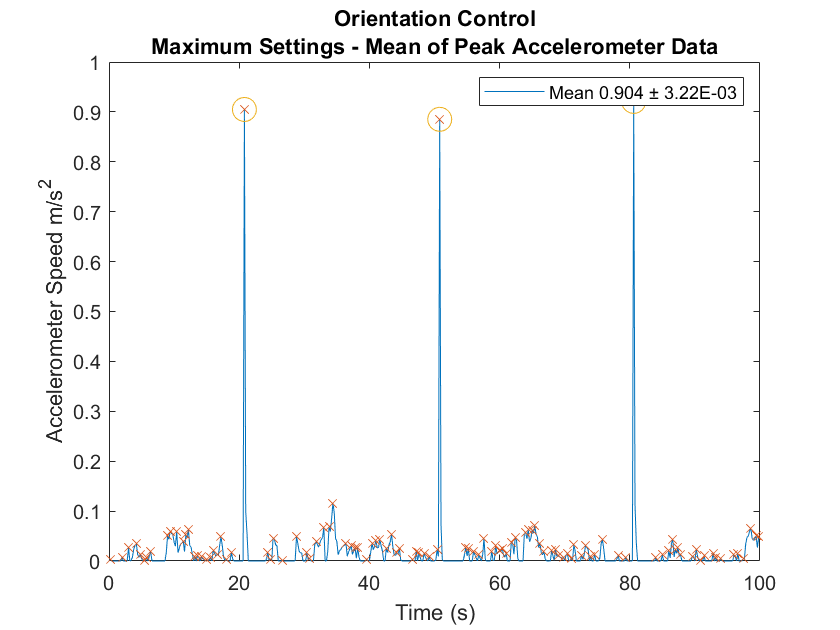


xlabel('Time (s)');
ylabel('Accelerometer Speed m/s^2')
title({'Orientation Control';'Maximum Settings - Mean of Peak Accelerometer Data'})
legend({mean},'Location','northeast')